## Recitation 3

We saw that the time t required to solve a banded matrix of size n × n with a bandwidth p = q scales like $t \sim n p^2$. In this problem, we will explore the ability of different solver to handle large, banded matrices.

**(a) **   Write a MATLAB program that determines the time required to solve a 500 × 500 banded system of the form Ax = b using naïve Gauss elimination and Gauss elimination with a banded solver for values of p = q from 1:499. The non-zero elements of the matrix A and the 500 × 1 forcing vector b should be randomly chosen for each value of p using the rand function in MATLAB. 

Make a plot of the number of non-zero elements in your matrix versus the value of p and make a log– log plot of the time required for the matrix solution by each method versus the value of p. 

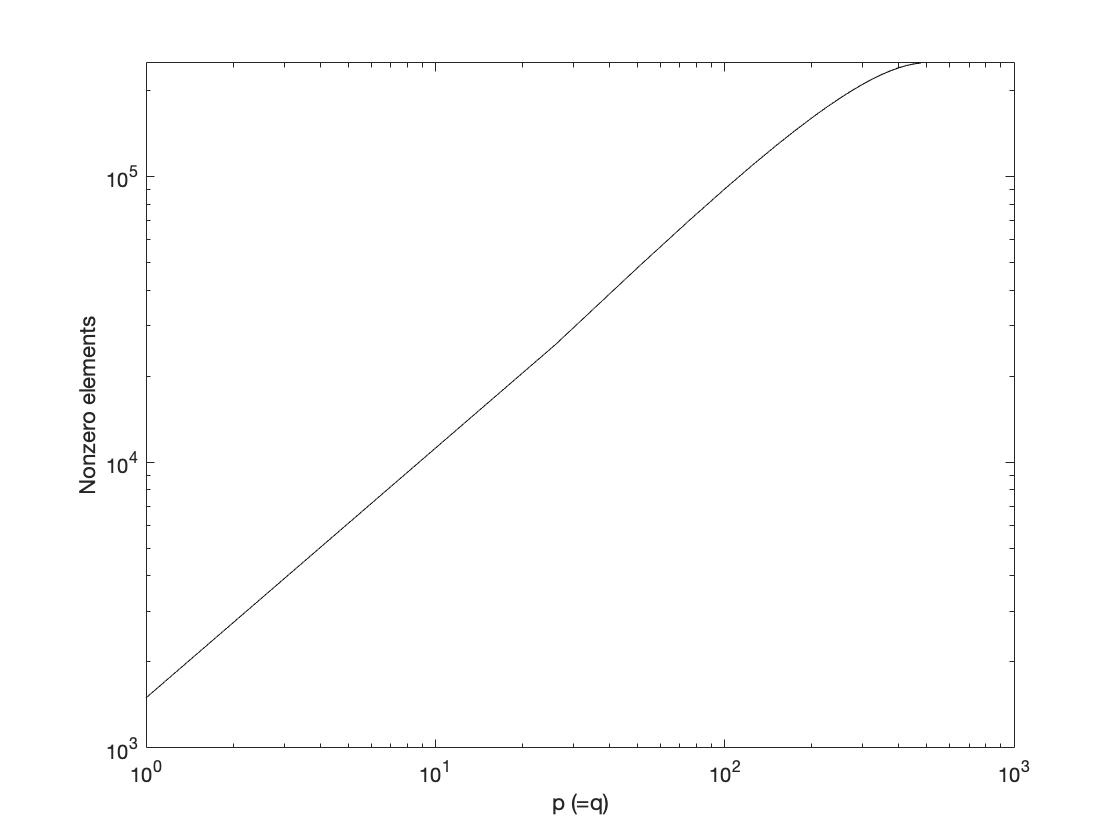

clc
close all

n = 500;                % size of matrix
pmin = 1;               % start value for p
pmax = 499;             % end value for p
dp = 25;                % interval in p
plist = (pmin:dp:pmax); % list of p values

niter = length(plist);          % number of iterations
sizelist = zeros(niter, 1);     % initialize array to store number of matrix nonzero elements
timesband = zeros(niter, 1);    % initialize array to store runtime of banded solver
timesnaive = zeros(niter, 1);   % initialize array to store runtime of naive solver

for iter=1:niter
    p = plist(iter);    % set p value
    q = p;              % assume q = p
    
    % generate random forcing vector
    b = rand(n, 1);
    
    % generate random banded matrix    
    A = zeros(n, n);
    for k=1:n
        for i=k:min(k+q, n)
            for j=k:min(k+p, n)
                A(i, j) = rand; % sample band entry randomly
            end
        end
    end
    sizelist(iter) = nnz(A);    % count number of nonzero elements
    
    % solve system using banded solver and record runtime
    tic
    linear_ngaussel_banded(A, b, p, q);
    timesband(iter) = toc;
    
    % solve system using naive solver and record runtime
    tic
    linear_ngaussel(A, b);
    timesnaive(iter) =  toc;
end

% plot number of nonzero elements vs p
figure(1);
loglog(plist, sizelist, '-k');
xlabel('p (=q)');
ylabel('Nonzero elements');

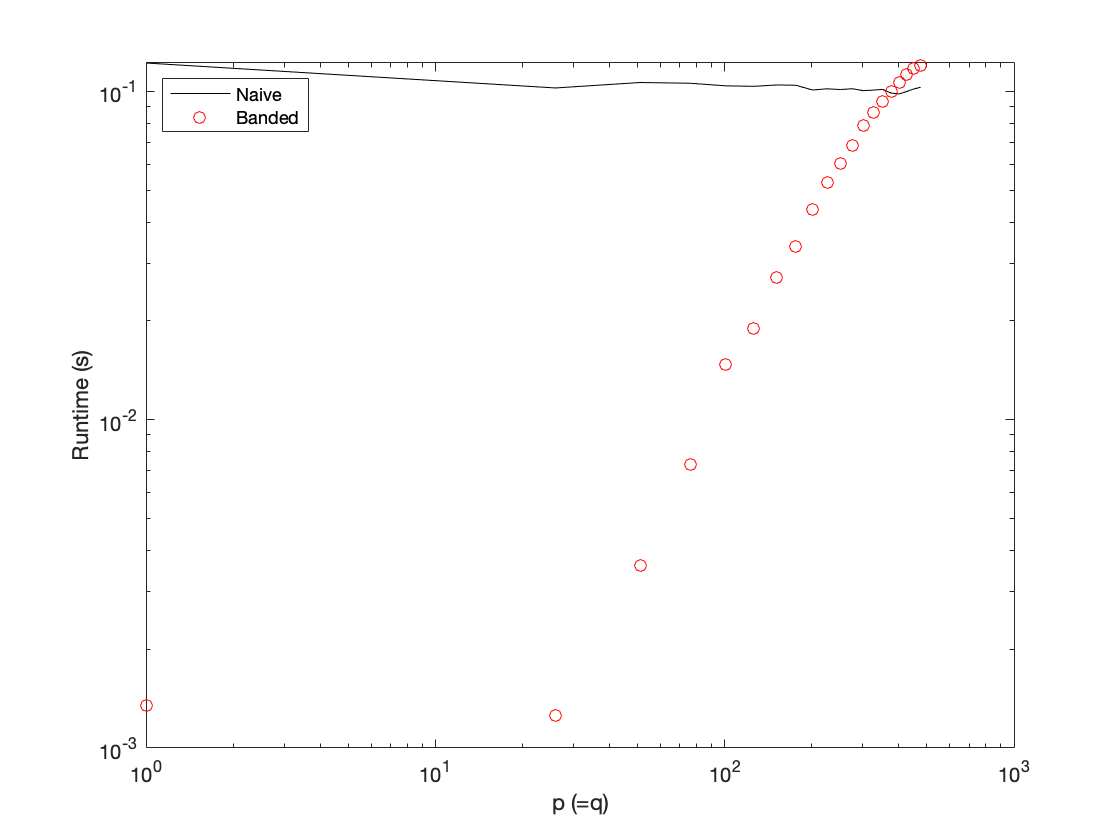


% plot runtime for banded and naive solver vs p
figure(2);
loglog(plist, timesnaive, '-k', 'DisplayName', 'Naive');
hold on;
loglog(plist, timesband, 'or', 'DisplayName', 'Banded');
hold off
xlabel('p (=q)');
ylabel('Runtime (s)');
legend('Location','Northwest');

The full solution is independent of *p*, as expected: $t \sim n^3$

The banded solution increases ~2 orders of magnitude in time for every order of magnitude in *p*, as expected: $t \sim np^2$.

**(b)**     Write a MATLAB program that determines the time required to solve a n × n banded system of the form Ax = b using naïve Gauss elimination and Gauss elimination with a banded solver for values of 𝑝 = 𝑞 = 1 and 𝑛 = 100: 50: 1000. The non-zero elements of the matrix A and the n × 1 forcing vector b should be randomly chosen for each value of n using the rand function in MATLAB. 				

How do you expect that ratio of the times by the two approaches to scales as a function of system size n? Make a log-log plot of the ratio of the times required for the matrix solution by each method versus the value of n. 			

*To get the time required for a given value of p or n in your program, you use the command tic to start to clock before you solve the matrix system and toc to stop the clock after you solve the matrix system. If you write t = toc, the value of the time will be stored in the variable t. *

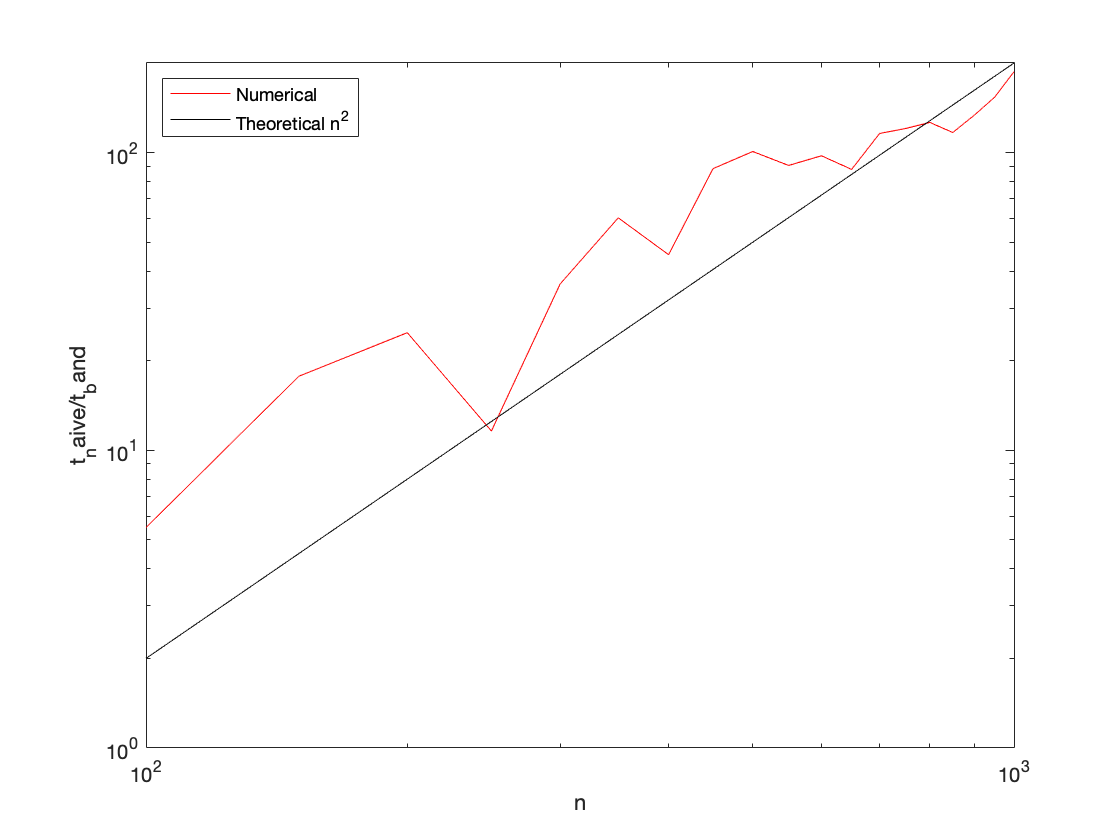

clc

p = 1;                      % set p value
q = 1;                      % set q value
nmin = 100;                 % set minimum matrix size
nmax = 1000;                % set max matrix size
dn = 50;                    % inverval in matrix sizes
niter = (nmax-nmin)/dn + 1; % total number of iterations


nlist = linspace(nmin, nmax, niter); % size of matrix
timesband = zeros(niter, 1);         % initialize array to store runtime of banded solver
timesnaive = zeros(niter, 1);        % initialize array to store runtime of naive solver

for iter=1:niter
    n = nlist(iter);    % set matrix size
    
    % generate random forcing vector
    b = rand(n, 1);
    
    % generate random banded matrix    
    A = zeros(n, n);
    for k=1:n
        for i=k:min(k+q, n)
            for j=k:min(k+p, n)
                A(i, j) = rand; % sample band entry randomly
            end
        end
    end

    % solve system using banded solver and record runtime
    tic
    linear_ngaussel_banded(A, b, p, q);
    timesband(iter) = toc;
    
    % solve system using naive solver and record runtime
    tic
    linear_ngaussel(A, b);
    timesnaive(iter) =  toc;
end

% plot runtime for banded and naive solver vs p
figure(3);
loglog(nlist, timesnaive./timesband, '-r', 'DisplayName', 'Numerical');
hold on;
loglog(nlist, (nlist.^2)./5000, '-k', 'DisplayName', 'Theoretical n^2');
hold off
xlabel('n');
ylabel('t_naive/t_band');
legend('Location','Northwest');

The ratio exhibits the approximately $n^2$ dependence that is expected $\sim n^3/(np^2) = (n/p)^2$. 

function x = linear_ngaussel(A, b)
% A = n x n matrix
% b = column vector, n x1
n = length(b);
x = zeros(n, 1);
% Perform the forward elimination
for k = 1:n-1
   for i = k+1:n
       m = A(i, k)/A(k, k);
       for j = k+1:n
           A(i, j) = A(i, j) - m * A(k, j);
       end
       b(i) =  b(i) - m * b(k);   
   end
end
%Perform back substitution
x(n) = b(n)/A(n, n);
for i=n-1:-1:1
    S = b(i);
    for j=i+1:n
        S = S - A(i, j) * x(j);
    end
    x(i) =  S/A(i, i);
end
% to print upper triangular matrix U do
% triu(A)
end

function x = linear_ngaussel_banded(A, b, p, q) 
% A = nxn matrix
% b = column vector, nx1
n = length(b);
x = zeros(n,1);
% Perform the forward elimination
for k=1:n-1
    for i=k+1:min(k+q,n)
        m = A(i,k)/A(k,k);
        for j=k+1:min(k+p,n)
            A(i,j) = A(i,j) - m * A(k,j); 
        end
        b(i) = b(i) - m * b(k); 
    end
end
% Perform the back substitution
x(n) = b(n)/A(n,n); 
for i=n-1:-1:1
    S=b(i);
    for j=i+1:min(i+p,n)
        S = S - A(i,j) * x(j); 
    end
    x(i) = S/A(i,i);
end
end